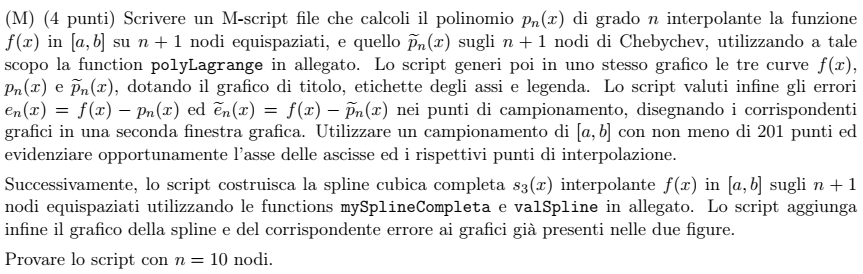

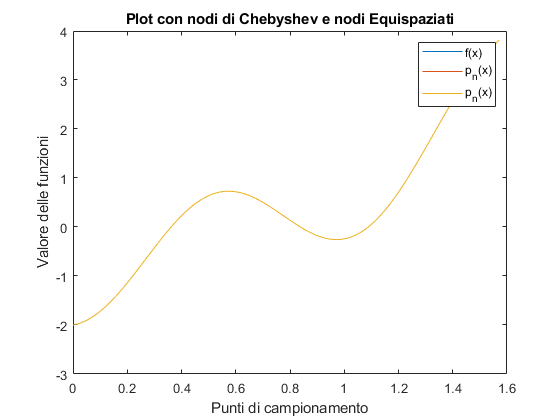

n = 20; a = 0; b = 0.5 * pi;
punticampionamento = 201;
f = @(x) ( exp(x) - cos(6*x) - 2 );
nodiEq = linspace( a, b, n+1 )';
nodiCheb = 0.5 * ( (b-a) * cos( 0.5*pi* ( 2*[0:n]' + 1 ) / (n+1) ) + (a+b) )';
xx = linspace(a,b,punticampionamento)';
[yEq,coeffEQ] = polyLagrange(nodiEq,f(nodiEq),xx);
[yCheb,coeffCheb] = polyLagrange (nodiCheb,f(nodiCheb),xx);
yy=f(xx);
yEq;
errEQ= yy-yEq;
errCheb = yy-yCheb;

%ph=plot(xx,yy,'-r',xx,yEq,'-b',xx,yCheb,'-k');
ph=plot(xx,[yy,yEq,yCheb]);
title('Plot con nodi di Chebyshev e nodi Equispaziati')
xlabel('Punti di campionamento')
ylabel('Valore delle funzioni')
legend('f(x)','p_{n}(x)','p_{n}(x)')

Spline

fp = @(x) ( exp(x) + 6*sin(6*x) );
yy = valSpline(mySplineCompleta(nodiEq,f(nodiEq),fp(xx(1)),fp(xx(end))), nodiEq, xx)

yy =    -2.0000
   -1.9988
   -1.9954
   -1.9897
   -1.9817
   -1.9715
   -1.9590
   -1.9444
   -1.9277
   -1.9088


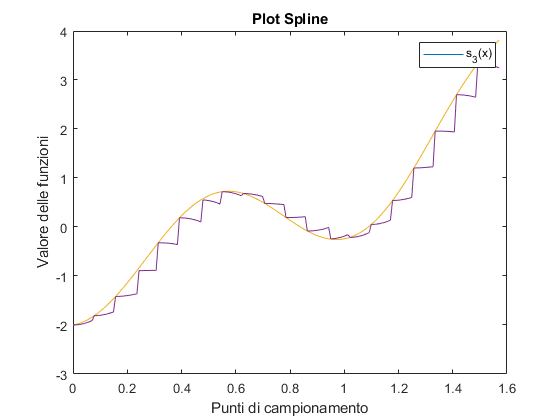

hold on
plot(xx,yy);
title('Plot Spline')
xlabel('Punti di campionamento')
ylabel('Valore delle funzioni')
legend('s_{3}(x)');